# **LAB:  Bearing Fault Monitoring and RUL Estimation**

**Name: AN GYEON HEAL**

**ID: 21900416**

**Date: 2024-10-04**

## **Instruction**

In this LAB, you are required to create a simple code for Fault Monitoring and RUL estimation

You can refer to RUL estimation tutorial codes and related papers

**Fault Monitoring**

- Detect Fault Status

- Display WARNING MESSAGE

**RUL Estimation **

- Estimate RUL similar to Tutorial codes

- The end of Life can be assumed when the repair is done

## Dataset

Raw Dataset of Bearing Velocity measured that shows a Bearing Life cycle before the repair is done. Also the velocity measurement after the repair is provided.

**Download** bearing  dataset for this lab: [[Download here](https://drive.google.com/file/d/1L9iz34MI8v469J30SCM6_38TT7TICXrX/view?usp=share_link)]

Using the given dataset, develop simple program for

- Bearing velocity measured 24 times per day

- Each measurement is L=8192 with Fs=2560Hz  

- Measurement for consecutive days until repair is done

First visualize the vibration signals in the time domain. 

clear; close all; clc;
addpath('../../Library')
load("RULdata/bearing-vel-fulldata-rul.mat");
% rows: vel measurements // cols: measurement time 
% idx_repair = 1431;

bearing=bearingFulldata(:,1:idx_repair);
bearingNew=bearingFulldata(:,idx_repair+1:end);

% Data Length for each measurement
% L=8192
L=length(bearing(:,1))

L = 8192

% Sampling Frequency
fs = 2560;
ts = 1/fs;
t = 0:ts:ts*(L-1);

% Day(time) unit upto repair
dataN=(length(bearing(1, :)));
d = (0:1:dataN)/24;

Plotting bearing velocity raw data

- Initial state:  Day=0 

- Just before repair:  Day=59

- After repair:  Day=60

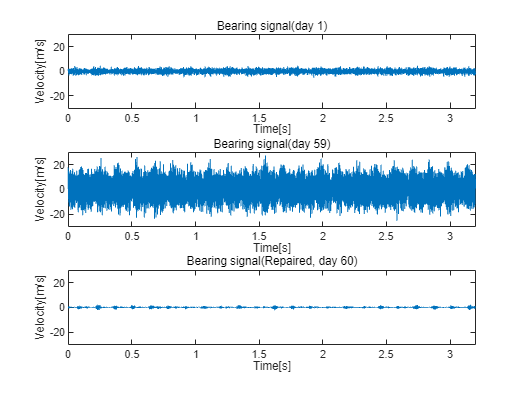

idx1 = 1;   idx2 = idx_repair;    idx3 = 1;

figure
subplot(3, 1, 1);       plot(t, bearing(:, idx1));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 1)');
subplot(3, 1, 2);       plot(t, bearing(:, idx2));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 59)');
subplot(3, 1, 3);       plot(t, bearingNew(:, idx3));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(Repaired, day 60)');

## **1. Data Exploration and Preprocessing**

**Time domain visualization **

This code is for visualizing time-domain measurements of bearing data. The dataset is measured 24 times per day, and each measurement consists of L=8192L=8192L=8192 samples, sampled at Fs=2560HzFs = 2560HzFs=2560Hz. The code plots each day's measurements on the time axis, allowing comparison of data over multiple days.

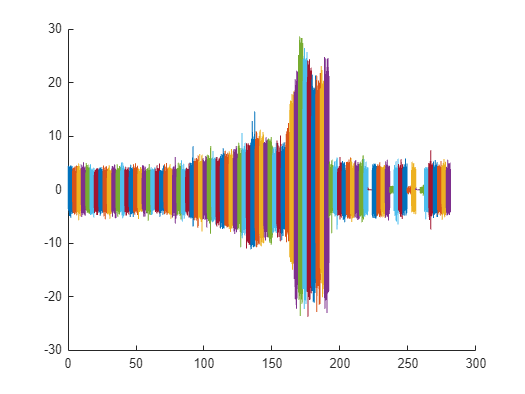

figure
hold on;
tstart = 0;
for day = 1:24:2104
    t = tstart + (1:L)/fs;
    plot(t, bearingFulldata(:,day))
    tstart = t(end);
end
hold off;

## 2. Spectral Kurtosis

Visualizing Spectral Kurtosis (SK) across different time measurements for bearing fault data. The goal is to analyze how the kurtosis changes over time and frequency, which helps in identifying faulty conditions in the system

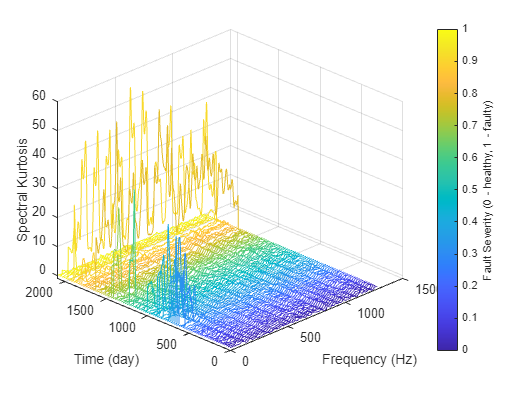

colors = parula(2104);
figure
hold on
wc = 128;
for times = 1:24:2104
    [SK, Fout] = pkurtosis(bearingFulldata(:,times), fs, wc);
    a = times*ones(size(Fout));
    plot3(Fout, times*ones(size(Fout)), SK, 'Color', colors(times, :))
end
hold off
xlabel('Frequency (Hz)')
ylabel('Time (day)')
zlabel('Spectral Kurtosis')
grid on
view(-45, 30)
cbar = colorbar;
ylabel(cbar, 'Fault Severity (0 - healthy, 1 - faulty)')

## **3. Spectrogram Analysis**

Performing a spectrogram analysis on two sets of bearing data: one representing a healthy bearing and the other representing a faulty bearing. The goal is to visualize the time-frequency representation of the velocity data and compare the peak frequencies of both healthy and faulty bearings.

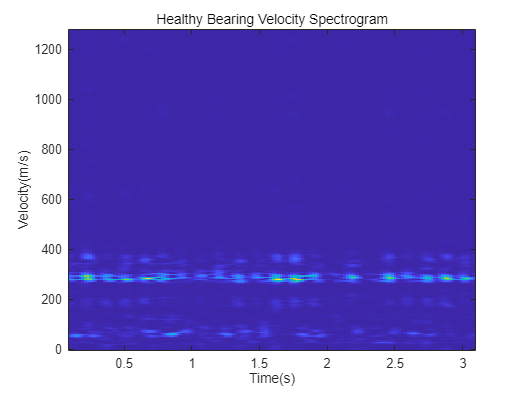

filtered_bearing = medfilt1(bearingNew(:, 1),5);

[~,fvec,tvec,P0] = spectrogram(filtered_bearing(:,1),500,450,512,fs);
clf;
imagesc(tvec,fvec,P0)
xlabel('Time(s)');
ylabel('Velocity(m/s)');
title('Healthy Bearing Velocity Spectrogram');
axis xy

[~,I0] = max(P0);               % Find out where the peak frequencies are located.
meanPeakFreq0 = mean(fvec(I0))  % Calculate mean peak frequency.

meanPeakFreq0 = 264.7078

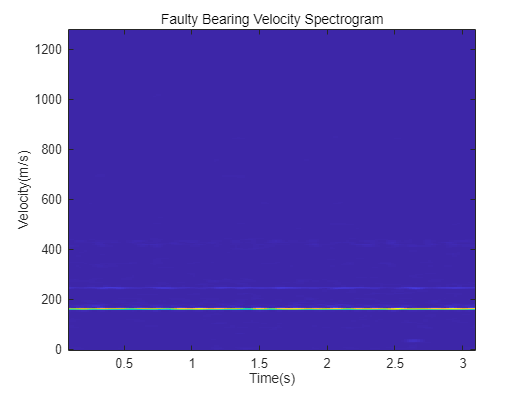

filtered_bearing = medfilt1(bearing(:, 1420),5);

[~,fvec,tvec,P0] = spectrogram(filtered_bearing(:,1),500,450,512,fs);
clf;
imagesc(tvec,fvec,P0)
xlabel('Time(s)');
ylabel('Velocity(m/s)');
title('Faulty Bearing Velocity Spectrogram');
axis xy

[~,I0] = max(P0);               % Find out where the peak frequencies are located.
meanPeakFreq0 = mean(fvec(I0))  % Calculate mean peak frequency.

meanPeakFreq0 = 165

## **4. Feature Extraction and Analysis**

### **Time Domain Feature Extraction**

This code performs feature extraction and visualization for bearing data in the time domain. It extracts time-domain features for 2104 time steps, plots them, and then applies a moving average filter to smooth the extracted features before plotting them again.

bearing_time_features = table;
for times = 1:2104
    bearing_time_features(times,:) = timeFeatures(bearingFulldata(:,times));
end

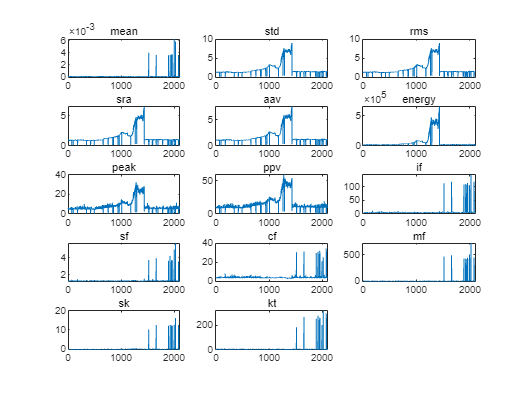

feature_names = {'mean', 'std', 'rms', 'sra', 'aav', 'energy', 'peak', 'ppv', 'if', 'sf', 'cf', 'mf', 'sk', 'kt'};
x = 1:2104;

figure;
hold on;
for i = 1:14
    subplot(5,3,i)
    plot(x, table2array(bearing_time_features(:, i)))
    title(feature_names{i});
end
hold off;

**Smoothing - moving average filter applied**

This code snippet is designed to smooth the time-domain features of the bearing data using a moving average filter, then visualize the smoothed features for `fc`, `rmsf`, and `rvf` over 2104 time steps.

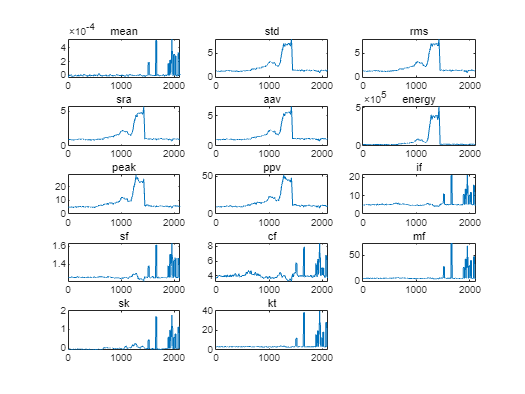

windowSize = 21; 

bearing_time_features_mv = bearing_time_features;
for i = 1:width(bearing_time_features)
    bearing_time_features_mv{:, i} = movmean(bearing_time_features{:, i}, windowSize);
end

feature_names = {'mean', 'std', 'rms', 'sra', 'aav', 'energy', 'peak', 'ppv', 'if', 'sf', 'cf', 'mf', 'sk', 'kt'};
x = 1:2104;
figure;
hold on;
for i = 1:14
    subplot(5,3,i)
    plot(x, table2array(bearing_time_features_mv(:, i)))
    title(feature_names{i});
end
hold off;

## **5. Frequency Domain Feature Extraction**

This code is designed to perform feature extraction in the frequency domain on bearing data, extracting three specific frequency-domain features: frequency center (`fc`), RMS frequency (`rmsf`), and root variance frequency (`rvf`). It then plots these features for 2104 time steps to visualize the trends over time.

bearing_freq_features = table;
for times = 1:2104
    bearing_freq_features(times,:) = freqFeatures(bearingFulldata(:,times));
end
% row 1 = fc, row 2 = rmsf, row 3 = rvf

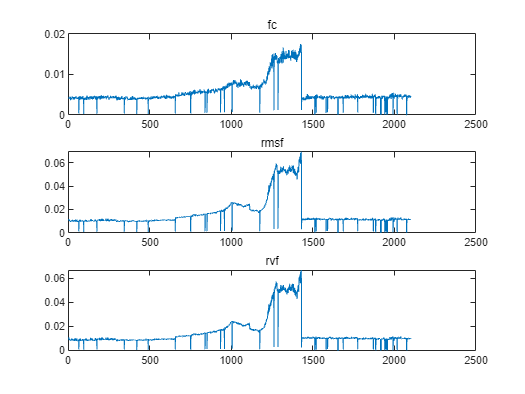

feature_names = {'fc', 'rmsf', 'rvf'};
x = 1:2104;
figure;
hold on;
for i = 1:3
    subplot(3,1,i)
    plot(x, table2array(bearing_freq_features(:, i)))
    title(feature_names{i});
end
hold off;

**Smoothing Datasets - moving average filter applied**

This code snippet is designed to smooth the frequency-domain features of the bearing data using a moving average filter, then visualize the smoothed features for `fc`, `rmsf`, and `rvf` over 2104 time steps.

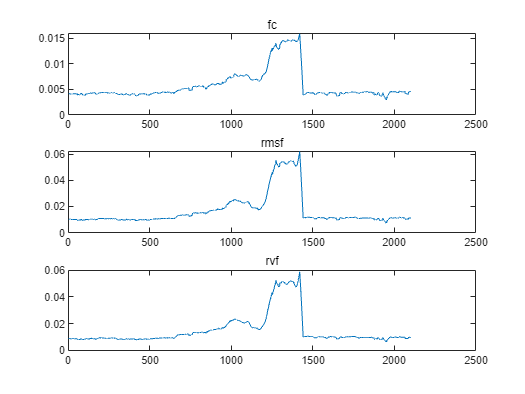

bearing_freq_features_mv = bearing_freq_features;
for i = 1:width(bearing_freq_features)
    bearing_freq_features_mv{:, i} = movmean(bearing_freq_features{:, i}, windowSize);
end

feature_names = {'fc', 'rmsf', 'rvf'};
x = 1:2104;
figure;
hold on;
for i = 1:3
    subplot(3,1,i)
    plot(x, table2array(bearing_freq_features_mv(:, i)))
    title(feature_names{i});
end
hold off;

## 6. Feature Postprocessing

### Feature Smoothing & Datetime Adding

This code is focused on postprocessing the features by combining both time-domain and frequency-domain features, applying a moving average filter, and creating a timetable for visualization and further analysis.

bearing_features = horzcat(bearing_freq_features, bearing_time_features);

windowSize = 5; 

bearing_features_mv = bearing_features;
for i = 1:width(bearing_features)
    bearing_features_mv{:, i} = movmean(bearing_features{:, i}, windowSize);
end

tm = datetime(2024, 4, 14) + days(1:59);
t = table;
i = 1;
for k = 1:59
    t(k,:) = bearing_features_mv(i,:);
    i  = i + 24;
end
t.time = tm'

t = 59×18 table
       fc          rmsf          rvf          mean         std       rms        sra        aav      energy     peak      ppv        if        sf        cf        mf         sk          kt         time   
    _________    _________    _________    ___________    ______    ______    _______    _______    ______    ______    ______    ______    ______    ______    ______    _________    ______    __________

    0.0041796     0.011106    0.0098548    -4.2318e-05    1.4216    1.4215    0.96413     1.1362    16557     5.7667    10.667    5.0722    1.2512    4.0543    5.9772    -0.041174    2.9773    2024-04-15
    0.0042053     0.010329    0.0089347    -1.5625e-05    1.3221    1.3221    0.89401     1.0552    14343      5.038       9.7    4.7741    1.2529    3.8088    5.6362    -0.036777    2.9886    2024-04-16
    0.0041993     0.010013    0.0085834    -9.5215e-06    1.2818    1.2817    0.86506      1.022    13458       5.19     9.976    5.0782    1.2541    4.0485    6.0001 

timeTable = table2timetable(t, "RowTimes","time")

timeTable = 59×17 timetable
       time          fc          rmsf          rvf          mean         std       rms        sra        aav      energy     peak      ppv        if        sf        cf        mf         sk          kt  
    __________    _________    _________    _________    ___________    ______    ______    _______    _______    ______    ______    ______    ______    ______    ______    ______    _________    ______

    2024-04-15    0.0041796     0.011106    0.0098548    -4.2318e-05    1.4216    1.4215    0.96413     1.1362    16557     5.7667    10.667    5.0722    1.2512    4.0543    5.9772    -0.041174    2.9773
    2024-04-16    0.0042053     0.010329    0.0089347    -1.5625e-05    1.3221    1.3221    0.89401     1.0552    14343      5.038       9.7    4.7741    1.2529    3.8088    5.6362    -0.036777    2.9886
    2024-04-17    0.0041993     0.010013    0.0085834    -9.5215e-06    1.2818    1.2817    0.86506      1.022    13458       5.19     9.976    5.0782    1

### Monotonicity Analyze (Feature Reduction)

This code performs a **Monotonicity Analysis** for feature reduction, aiming to select the most important features based on their monotonicity score. Here's the step-by-step explanation of each section:

breaktime = datetime(2024, 5, 7);
breakpoint = find(timeTable.time < breaktime, 1, 'last');
trainData = timeTable(1:breakpoint, :);

featureImportance = monotonicity(trainData, 'WindowSize', 0);
sum(featureImportance)

ans = 1×17 table
      fc        rmsf        rvf        mean        std        rms        sra        aav      energy      peak       ppv         if          sf         cf         mf         sk          kt   
    _______    _______    ________    _______    _______    _______    _______    _______    _______    ______    ________    _______    ________    _______    _______    _______    ________

    0.14286    0.14286    0.047619    0.14286    0.14286    0.14286    0.14286    0.14286    0.14286    0.2381    0.047619    0.14286    0.047619    0.14286    0.14286    0.33333    0.047619


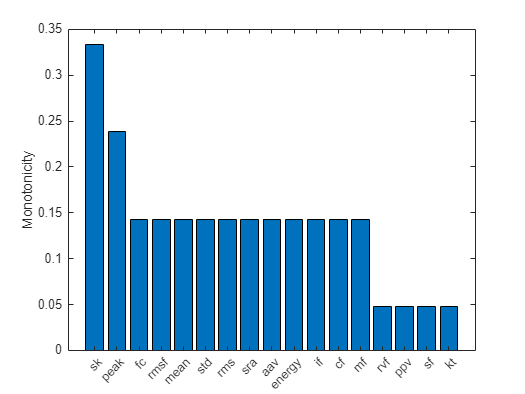

helperSortedBarPlot(featureImportance, 'Monotonicity');

trainDataSelected = trainData(:, featureImportance{:,:}>0.2);
featureSelected = timeTable(:, featureImportance{:,:}>0.2);

## **7. Selection of Features**

### **PCA**

Performs feature selection and dimensionality reduction using Principal Component Analysis (PCA). First, it normalizes the selected training data (`trainDataSelected`) by calculating the mean and standard deviation. After normalization, PCA is applied to extract the primary components (`PCA1` and `PCA2`). The code then visualizes the data in the space of the first two principal components using a scatter plot, with a color bar indicating the time progression. Additionally, it plots `PCA1` and `PCA2` over time and designates `PCA1` as the health indicator, which is also plotted to track the machine's condition over time.

meanTrain = mean(trainDataSelected{:,:});
sdTrain = std(trainDataSelected{:,:});
trainDataNormalized = (trainDataSelected{:,:} - meanTrain)./sdTrain;
coef = pca(trainDataNormalized);

The mean, standard deviation and PCA coefficients are used to process the entire data set.

PCA1 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
PCA2 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

Visualize the data in the space of the first two principal components.

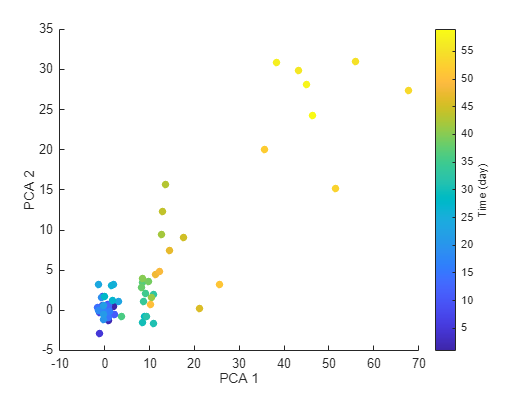

figure
numData = size(timeTable, 1);
scatter(PCA1, PCA2, [], 1:numData, 'filled')
xlabel('PCA 1')
ylabel('PCA 2')
cbar = colorbar;
timeUnit = 'day';
ylabel(cbar, ['Time (' timeUnit ')'])

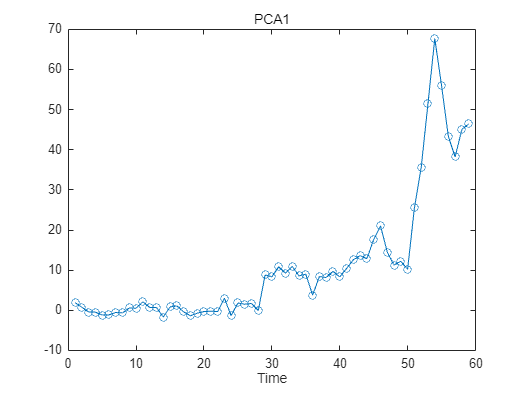


figure
plot(PCA1, '-o')
xlabel('Time')
title('PCA1')

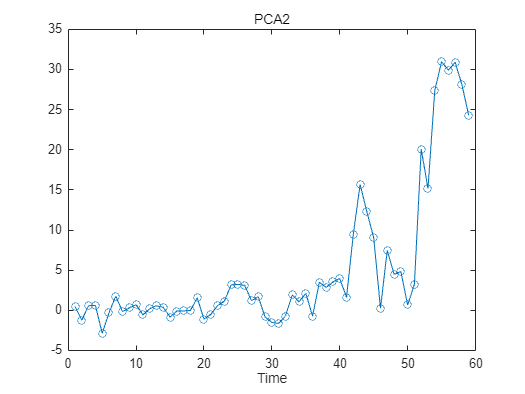

figure
plot(PCA2, '-o')
xlabel('Time')
title('PCA2')

healthIndicator = PCA1;

Visualize the health indicator.

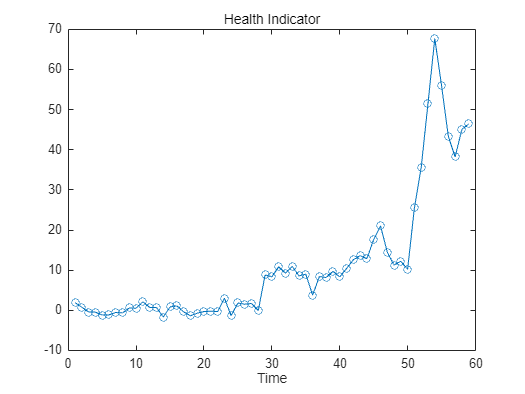

figure
plot(healthIndicator, '-o')
xlabel('Time')
title('Health Indicator')

## 8. Fault Monitoring and Warning

Exponential degradation model is defined as


$$h\left(t\right)=\phi +\theta \;\exp \left(\beta \;t+\epsilon \;-\frac{\sigma^2 }{2}\right)$$


where $h\left(t\right)$ is the health indicator as a function of time. $\phi \;$is the intercept term considered as a constant. $\theta$ and $\beta \;$ are random parameters determining the slope of the model, where $\theta \;$is lognormal-distributed and $\beta \;$is Gaussian-distributed. At each time step $t$, the distribution of $\theta \;$and $\beta \;$is updated to the posterior based on the latest observation of $h\left(t\right)$. $\epsilon \;$ is a Gaussian white noise yielding to $N\left(0,\sigma^2 \right)$. The $-\frac{\sigma^2 }{2}$ term in the exponential is to make the expectation of $h\left(t\right)$ satisfy

$E\left\lbrack h\left(t\right)\left|\theta \;,\beta \;\right.\right\rbrack \;=\;\phi +\theta \;\exp \left(\beta \;t\right)$.

Here an Exponential Degradation Model is fit to the health indicator extracted in the last section, and the performances is evaluated in the next section.

First shift the health indicator so that it starts from 0.

healthIndicator = healthIndicator - healthIndicator(1);

The selection of threshold is usually based on the historical records of the machine or some domain-specific knowledge. Since no historical data is available in this dataset, the last value of the health indicator is chosen as the threshold. It is recommended to choose the threshold based on the smoothed (historical) data so that the delay effect of smoothing will be partially mitigated.

threshold = healthIndicator(end);

If historical data is available, use `fit` method provided by `exponentialDegradationModel` to estimate the priors and intercept. However, historical data is not available for this wind turbine bearing dataset.

 The prior of the slope parameters are chosen arbitrarily with large variances ($E\left(\theta \right)=1,\;\textrm{Var}\left(\theta \right)\;={10}^6 ,E\left(\beta \right)=1,\textrm{Var}\left(\beta \right)={10}^6$) so that the model is mostly relying on the observed data. Based on $E\left\lbrack h\left(0\right)\right\rbrack =\phi +E\left(\theta \right)$, intercept $\phi \;$is set to $-1$ so that the model will start from 0 as well. 

The relationship between the variation of health indicator and the variation of noise can be derived as


$$\Delta h\left(t\right)\approx \left(h\left(t\right)-\phi \;\right)\Delta \epsilon \left(t\right)$$


Here the standard deviation of the noise is assumed to cause 10% of variation of the health indicator when it is near the threshold. Therefore, the standard deviation of the noise can be represented as $\frac{10%\cdot \textrm{threshold}}{\textrm{threshold}-\phi \;}$.

The exponential degradation model also provides a functionality to evaluate the significance of the slope. Once a significant slope of the health indicator is detected, the model will forget the previous observations and restart the estimation based on the original priors. The sensitivity of the detection algorithm can be tuned by specifying `SlopeDetectionLevel`. If p value is less than `SlopeDetectionLevel`, the slope is declared to be detected. Here `SlopeDetectionLevel` is set to 0.05.

Now create an exponential degradation model with the parameters discussed above.

mdl = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

## 9. RUL Estimation

You need to explain the process cleary and analyze the results

Use `predictRUL` and `update` methods to predict the RUL and update the parameter distribution in real time.

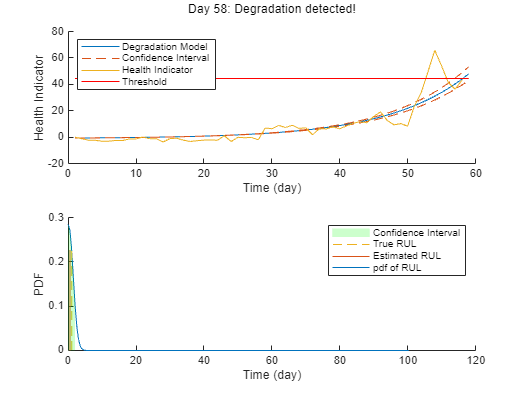

% Keep records at each iteration
totalDay = length(healthIndicator) - 1;
estRULs = zeros(totalDay, 1);
trueRULs = zeros(totalDay, 1);
CIRULs = zeros(totalDay, 2);
pdfRULs = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(mdl, [currentDay healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentDay healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator, mdl, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    estRULs(currentDay) = estRUL;
    trueRULs(currentDay) = trueRUL;
    CIRULs(currentDay, :) = CIRUL;
    pdfRULs{currentDay} = pdfRUL;
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

Here is the animation of the real-time RUL estimation.

## 10. Performance Analysis

$\alpha$-$\lambda$ plot is used for prognostic performance analysis [5], where $\alpha \;$bound is set to 20%. The probability that the estimated RUL is between the $\alpha$ bound of the true RUL is calculated as a performance metric of the model:


$$\Pr \left(r^* \left(t\right)-\alpha r^* \left(t\right)<r\left(t\right)<r^* \left(t\right)+\alpha r^* \left(t\right)\left|\Theta \left(t\right)\right.\right)$$


where $r\left(t\right)$ is the estimated RUL at time $t$, $r^* \left(t\right)$ is the true RUL at time $t$, $\Theta \left(t\right)$ is the estimated model parameters at time $t$.

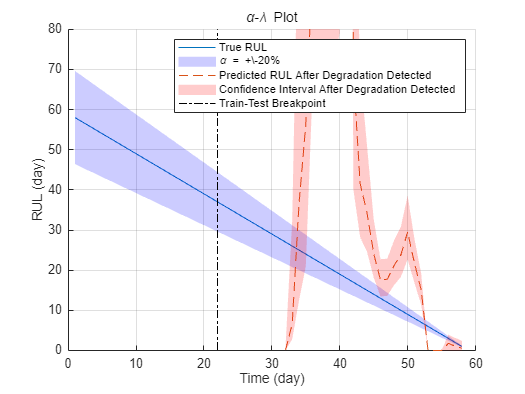

alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
    pdfRULs, detectTime, breakpoint, timeUnit);
title('\alpha-\lambda Plot')

Since the preset prior does not reflect the true prior, the model usually need a few time steps to adjust to a proper parameter distribution. The prediction becomes more accurate as more data points are available.

Visualize the probability of the predicted RUL within the $\alpha \;$bound.

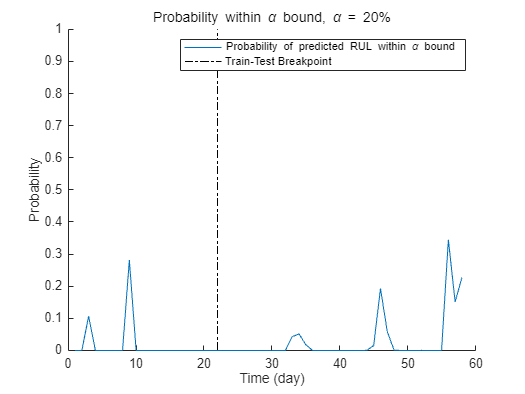

figure
t = 1:totalDay;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

## 11. Discussion 

### **11.1. Data Analysis**

In this study, various techniques were employed to monitor bearing fault progression and estimate the Remaining Useful Life (RUL) using a comprehensive approach to data analysis. The process began with time-domain feature extraction, where statistical metrics such as mean, standard deviation, root mean square (RMS), and spectral kurtosis were calculated from the bearing dataset. These features enabled an initial visualization of the bearing's operational condition over time, allowing the identification of key points that could signify the onset of failure.

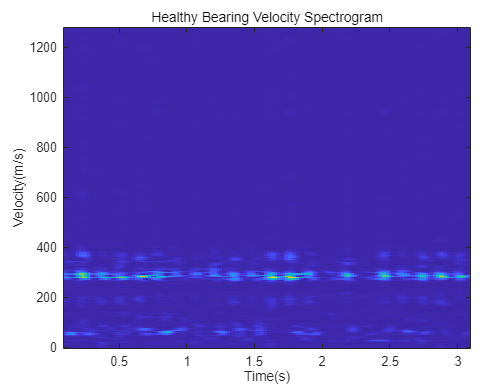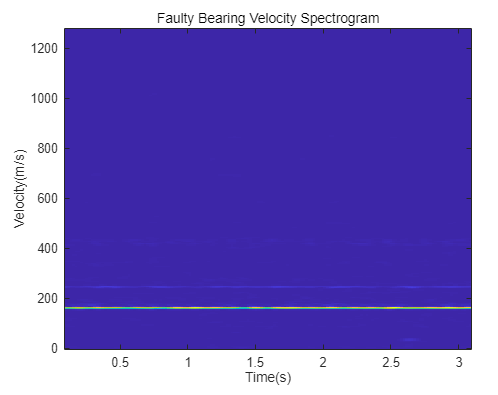

When analyzing the spectrogram, it was observed that before the bearing failure and after the repair, the velocity in the time domain ranged between 200 and 400. However, at the point of failure, the velocity dropped below 200.

### 11.2. Feature Extraction & Smoothing

Following this, frequency-domain features were extracted using the Fast Fourier Transform (FFT), capturing the vibrational characteristics of the bearings. Features such as frequency center, RMS frequency, and root variance frequency provided a more detailed perspective on the dynamic behavior of the machine, supplementing the insights gained from the time-domain analysis.

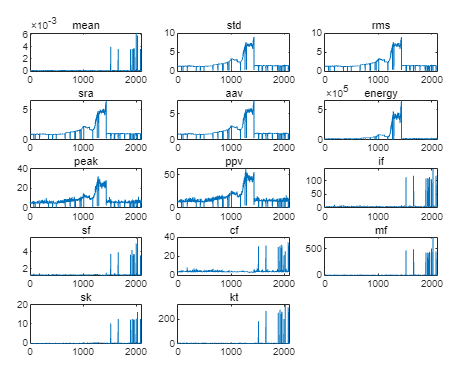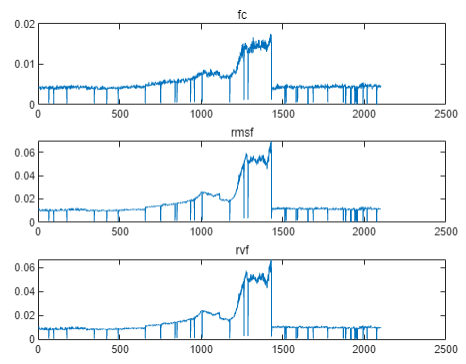

When extracting and plotting the time-domain and frequency-domain features, the presence of outliers was identified. These outliers could negatively affect prognosis, so it was necessary to remove the noise.

To address the presence of noise in the data, which can negatively impact RUL predictions, a moving average filter was applied. This filtering step was critical in smoothing the extracted features, reducing short-term fluctuations and ensuring that long-term trends, essential for accurate health monitoring, were preserved.

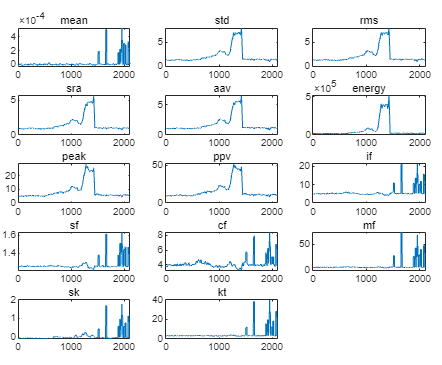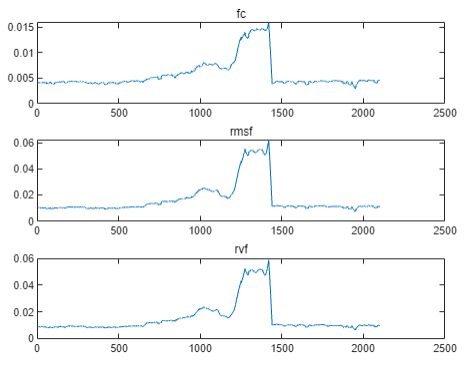

After applying the moving average filter, a significant reduction in noise was observed.

### 11.3. Feature Selection (Monotonicity)

Feature selection was performed using the monotonicity criterion, prioritizing features that demonstrated a consistent trend over time as the machine approached failure. This step was instrumental in reducing the complexity of the model and focusing on the most informative features for RUL estimation.

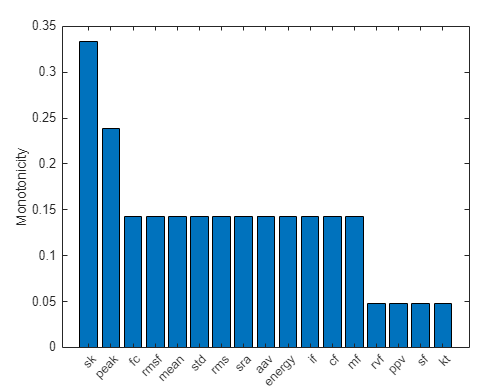

Upon examining monotonicity, it was found that the skewness and peak values showed the most consistent trends. Among these, skewness was selected for RUL estimation.

### 11.4. Feature Reduction (PCA) & Bearing Fault Progonosis

Subsequently, Principal Component Analysis (PCA) was utilized to further reduce the dimensionality of the feature set, retaining the most significant variance within the data. The first principal component (PCA1) emerged as a key health indicator, with its progression over time correlating strongly with the degradation of the bearing. The use of PCA1 as a health indicator provided a robust means of visualizing the machine's overall condition and identifying trends indicative of impending failure.

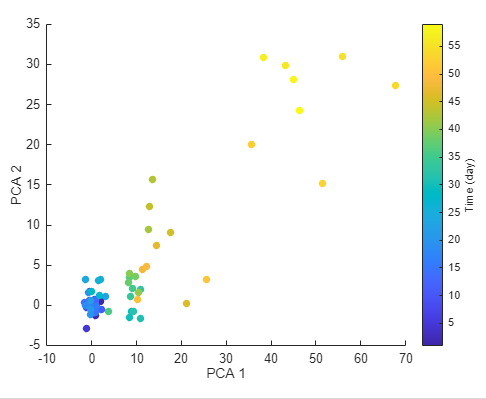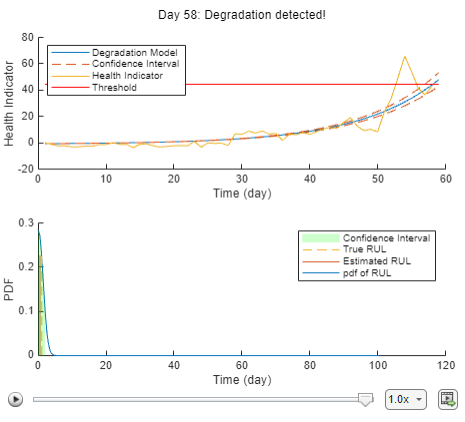

Based on the PCA analysis, PCA 1 was used as the health indicator, and it was successfully applied as a metric for predicting bearing failure. As a result, the bearing failure prediction was carried out successfully.

## Reference

**Wind Turbine High-Speed Bearing Prognosis**